# Transport  and Mobility Modelling 

# PART A

## Q1. Demand modelling

A new policy is proposed in the UK which aims to affect daily commutes (travel-to-work journeys). The policy is defined as follows: 

• Discourage long commutes (≥ 10 km, one way), originating in a densely populated area i (mi ≥ 10,000), by introducing a daily 1 pence per km fee for any such trips. 

• Encourage long commutes (≥ 10 km, one way), originating in rural, sparsely populated areas (mi < 10,000), by providing a daily subsidy of £2 per trip. 

For the purpose of this analysis, you should assume that the UK is made up of a set of zones i, with populations mi , and pairwise distances di,j (km) between zones j ̸=i.

### a. Net-positive or Net-negative

The Radiation model is in the form:


$$T_{i,j} = T_i \frac{P_iP_j}{(P_i+S_{i,j})(P_i+P_j+S_{i,j})$$


T_i,j is the number of trips from i to j, T_i is the number of trips originating in i (a product of employment rate and population of the area), P is the population of the area, and S is the sum of the populations of areas within the circle centred at i extending to j not including the areas i and j.

Start by assessing current situation..

The total number of trips is therefore given by:


$$\sum T_{i,j} = \sum_{j=1}^n\sum_{i=1}^nT_i\frac{P_iP_j}{(P_i + S_{i,j})(P_i + P_j+S_{i,j})$$


where 


$$S_{i,j} = \sum_{k=1}^nP_k \vert (d_{k,i}\leq d_{i,j}, k \neq i, j , i \neq j)$$


The benefit to the UK treasury occurs for every pairing of origin-destination areas where the origin population is greater than or equal to 10000, and the distance between the pair is greater than 10km. For each of these events the fee is £0.01 multiplied by the distance and the number of trips.

And so the benefit B: (distance in kM)


$$B = \sum_{i=1}^n \sum_{j=1}^n 0.01 d_{i,j} T_{i,j}  |(d_{i,j} \geq 10, P_i \geq10000, i \neq j)
$$


The cost to the UK treasury is £2 multiplied by the number of trips where the distance is greater than 10km and the population of the origin area is less than or equal to 10000.

And so the cost C:


$$C = \sum_{i=1}^n \sum_{j=1}^n 2 T_{i,j} | (P_i < 10000, d_{i,j} \geq 10)$$


With T_i,j  and S_i,j defined as above.

The **net cos**t is therefore B - C, where if this value is positive it is net-positive for the UK treasury.

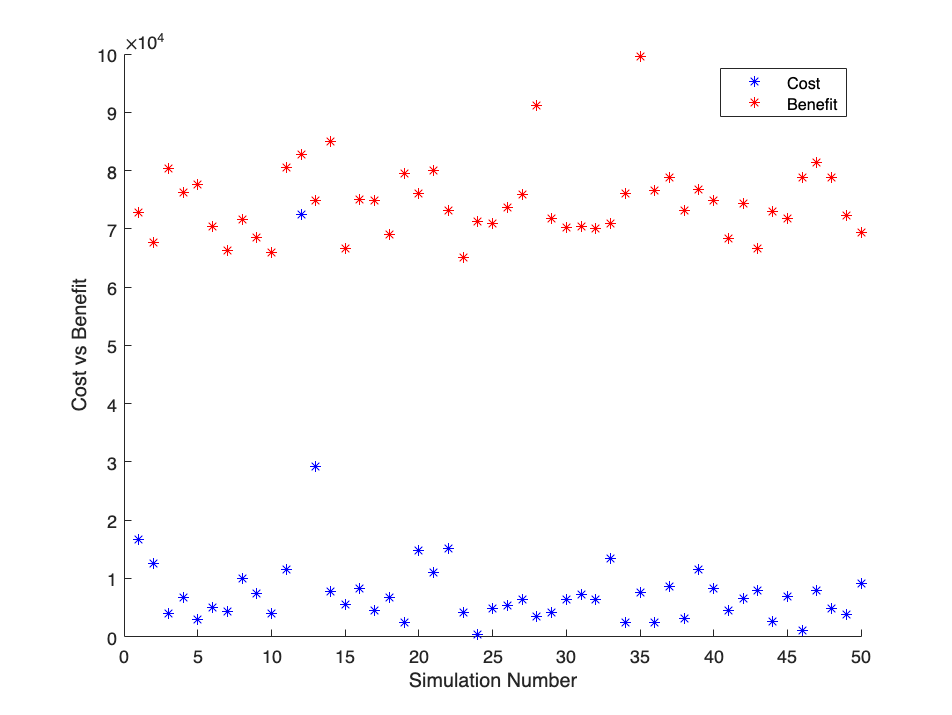

% run simulation n times
n = 50;
figure;
hold on
cost_v = [];
benefit_v = [];
for sim = 1:n
    % Define parameters
    numAreas = 50;  % Number of towns
    population = randi([1, 50000], 1, numAreas); % Random pop for each area
    distanceMatrix = randi([1, 100], numAreas, numAreas); % Random distance mat
    
    % Initialize T_ij matrix
    T_ij = zeros(numAreas, numAreas);
    
    % Calculate S_ij
    S_ij = zeros(numAreas, numAreas);
    for i = 1:numAreas
        for j = 1:numAreas
            if i ~= j
                S_ij(i, j) = sum(population(distanceMatrix(:, i)...
                    <= distanceMatrix(i, j) & (1:numAreas)' ~= i & (1:numAreas)' ~= j));
            end
        end
    end
    cost = 0;
    benefit = 0;
    % Calculate T_ij
    for i = 1:numAreas
        for j = 1:numAreas
            if i ~= j
                numerator = population(i) * population(j);
                denominator = (population(i) + S_ij(i, j)) * (population(i)...
                    + population(j) + S_ij(i, j));
                T_ij(i, j) = population(i) * numerator / denominator;
            end
        end
    end
    for i = 1:numAreas
        for j = 1:numAreas
            if population(i) >= 10000 && distanceMatrix(i, j) >= 10
                % Calculate benefit
                benefit = benefit + 0.01 * T_ij(i, j) * distanceMatrix(i,j);
            end
            
            if distanceMatrix(i, j) >= 10 && population(i) < 10000
                % Calculate cost
                cost = cost + 2 * T_ij(i, j);
            end
        end
    end

    cost_v(sim) = cost;
    benefit_v(sim) = benefit;
    
end
plot(1:sim,cost_v,'*',Color='b',DisplayName='Cost');
plot(1:sim,benefit_v,'*', Color='r', DisplayName='Benefit');
xlabel('Simulation Number')
ylabel('Cost vs Benefit')
legend

With this random silulation set-up it appears that the benefit is nearly always > cost and so in this simulation it is net-positive however this is not representative of the UK.

### b. Percentage of people affected by the policy

The percentage will be:


$$\frac{\sum T_{i,j} |(P_i\geq10000 , d_{i,j}\geq10) + T_{i,j} |(P_i<10000 , d_{i,j}\geq10)}{\sum T_{i,j}|(i\neq j )$$


This is the sum of all trips greater than 10km from densely populated areas, and the sum of all trips greater than 10km from rural areas, divided by the total number of trips occuring.

However, if considering the sum of all trips from both P  >= 10000 and P < 10000, this sum effects people from all population sizes, and the only dependency becomes the trip distance.


$$\frac{\sum T_{i,j} |d_{i,j}\geq10}{\sum T_{i,j}$$


(multiplied by 100)

% for the example
numer = 0;
totalTrips = sum(sum(T_ij));
for i = 1:numAreas
        for j = 1:numAreas
            if distanceMatrix(i, j) >= 10
                % numerator
                numer = numer + T_ij(i,j);
            end     
        end
end

% in this simulation
percentage_effected = (numer/totalTrips) * 100

percentage_effected = 25.3264

### c. Six city system


$$\matrix{
\text{City}    	&  \text{x} &  \text{y}& P_i
 \cr
A		& 0 			&0		&50000			 \cr
B		& 5 			&5		&20000			\cr C		& 10 			&0		&50000			\cr D	& 0 			&-7		&20000			\cr E		& -7			& -3		&18000			\cr F		& -12 			&6		&15000			\cr
}$$


#### i. How many trips originate in A and terminate in C

x = [0,5,10,0,-7,-12];
y = [0,5,0,-7,-3,6];
p = [50000, 20000, 50000, 20000, 18000, 15000];

% make a origin - destination distance matrix
d_ij = zeros(6,6);

for i = 1:length(x) % origin
    for j = 1:length(y) % destination
        x_dist = abs(x(i) - x(j));
        y_dist = abs(y(i) - y(j));
        d_ij(i,j) = sqrt(x_dist^2 + y_dist^2);
    end
end

% trips originating in A
employ = 0.755  % the national employment rate from ONS 2023

employ = 0.7550

T_a = p(1) * employ

T_a = 37750


% s term
S_a = 0;
for i = 1: length(d_ij)
    if d_ij(i,1) < d_ij(3,1) && i~=1  && i~=3 % exclude start/end
        S_a = S_a + p(i);
    end
end

T_ac = T_a*(p(1)*p(3))/((p(1)+ S_a)*(p(1)+p(3)+S_a));

% trips going from A to C:
round(T_ac)

ans = 5531

#### ii. What is the ratio of T_ac / T_ca

T_c = p(3) * employ

T_c = 37750


% s term
S_c = 0;
for i = 1: length(d_ij)
    if d_ij(i,3) < d_ij(1,3) && i~=1 && i~=3 % exclude start/end
        S_c = S_c + p(i);
    end
end
S_c

S_c = 20000


T_ca = T_c*(p(1)*p(3))/((p(3)+ S_c)*(p(1)+p(3)+S_c));

% ratio
ratio_ac_ca = T_ac / T_ca

ratio_ac_ca = 0.4923

More trips go from C to A than vice versa.

## Q2. Assignment modelling

#### a. Derive minimisation problems that you would solve to determine the UE and SO assignments

The links in the problem have costs:

$c_1(x_1) = a + x_1
$  and  $c_2(x_2) = 1 + bx_2$

Subject to:


$$x_1+x_2 = d$$



$$x_1,x_2 \geq 0$$


**User Equilibrium **occurs when the costs for either route become equal:


$$a+x_1 =1+{\textrm{bx}}_2$$



$$x_1 +x_2 =d$$


Solved such that:


$$x_1 =\frac{-a+\textrm{bd}+1}{b+1},x_2 =\frac{a+d-1}{b+1}$$


Whereas the **system optimal** solution considers when the total system travel time is minimised, and so the total travel time is the sum of the route costs multiplied by the respective flows:

Minimise:


$$\begin{array}{l}
{f\;=\;\textrm{ax}}_1 +x_1^2 +x_2 +{\textrm{bx}}_2^2 \\
x_1 +x_2 =d
\end{array}$$


This can be solved graphically (or using optimisation software), using f as an objective function, finding the minimum value of f that meets the demand constraint (plotting x_2 against x_1, f in green, constraint in red, for a=0.4, b=0.7, d= 1):

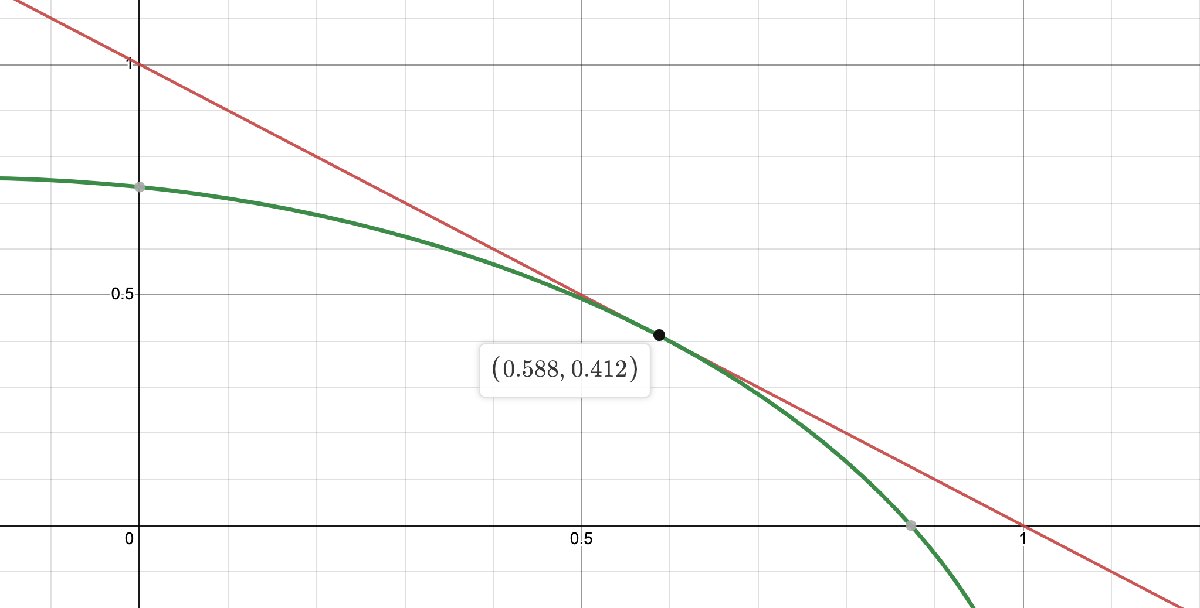

% define minimisation problem for User Equilibrium and System Optimal
a_var = 0.4;
b_var = 0.7;
d_var = 1;

H = [1, 0; 0, b_var]; % x^2 coefficients
f = [a_var; 1]; % x coefficients
Aeq = [1, 1];
beq = d_var;
options = optimoptions('quadprog', 'Display', 'off');

x_ue = UE_sol(H, f, Aeq, beq, options)

x_ue =     0.7647
    0.2353


x_so = SO_sol(H, f, Aeq, beq, options) % the quadratic coefficients *2

x_so =     0.5882
    0.4118


#### b. Price of Anarchy (PoA)

The PoA is the ratio of User Equilibrium Cost over the System Optimal Cost

In this case:


$$\textrm{POA}=\frac{\sum_i x_i^{\textrm{UE}} c_i }{\sum_i x_i^{\textrm{SO}} c_i }=\;\frac{{x_1^{\textrm{UE}} c}_1 \left(x_1^{\textrm{UE}} \right)+x_2^{\textrm{UE}} c_2 \left(x_2^{\textrm{UE}} \right)}{{x_1^{\textrm{SO}} c}_1 \left(x_2^{\textrm{SO}} \right)+{x_1^{\textrm{SO}} c}_2 \left(x_2^{\textrm{SO}} \right)}$$


#### c. Varying demand for fixed a and b values

clf;
% Initialize matrices to store solutions
d_values = 0:0.01:1; % up to d=1 as thats the interesting bit
x_ue_vals = zeros(length(d_values), 2); 
x_so_vals = zeros(length(d_values), 2); 

cost_ue = zeros(length(d_values),1);
cost_so = zeros(length(d_values),1);

% Solve the UE problem for each demand value
for i = 1:length(d_values)
    d = d_values(i);

% Define matrix H, f, and equality constraint
    H = [1, 0; 0, b_var];
    f = [a_var; 1];
    Aeq = [1, 1];
    beq = d;
    
% Solve the quadratic programming problem using quadprog
    x_ue = quadprog(H, f, [], [], Aeq, beq,[0,0],[],[], options);
    x_so = quadprog(2*H, f, [],[], Aeq, beq,[0,0],[],[], options); 
    
% Store the solution
    x_ue_vals(i, :) = x_ue';
    x_so_vals(i, :) = x_so';

    cost_ue(i) = x_ue_vals(i,1)*(a_var + x_ue_vals(i,1)) + x_ue_vals(i,2)...
        *(1+b_var*x_ue_vals(i,2));
    cost_so(i) = x_so_vals(i,1)*(a_var + x_so_vals(i,1)) + x_so_vals(i,2)...
        *(1+b_var*x_so_vals(i,2));
end

% POA 
poa = cost_ue./cost_so;
% find max POA
max_poa = max(poa)

max_poa = 1.0967

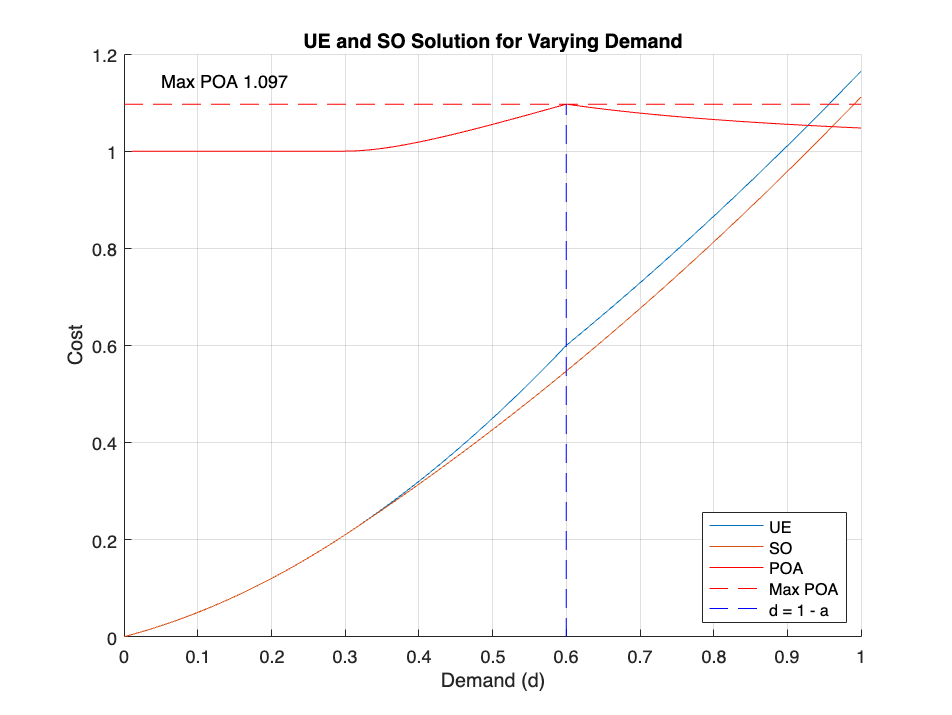

% Plot the results
figure;
hold on
plot(d_values, cost_ue, '-', 'DisplayName', 'UE');
plot(d_values, cost_so, '-', 'DisplayName', 'SO');
plot(d_values, poa, 'r-', 'DisplayName', 'POA');
% plot horizontal line for max poa
plot([0,max(d_values)],[max_poa, max_poa], 'r--', 'DisplayName','Max POA')
% plot where d=1-a
plot([1-a_var,1-a_var],[0,max_poa],'b--', 'DisplayName','d = 1 - a')

legend(Location="southeast");
xlabel('Demand (d)');
ylabel('Cost');
title('UE and SO Solution for Varying Demand');
text(0.05,max_poa+0.05,sprintf('Max POA %.3f', max_poa));
grid on;

The range of d chosen above has been decided by considering the original link cost functions, and the point of maximum POA. For 0 < a,b < 1 the maximum POA will always occur at d = 1 - a (for *a* within the bounds specified) and so d is not shown above 1 as the POA remains slowly tapering off from there onwards. As b tends to 1, and a tends to 1, the POA tends to 1.

#### d. Varying a and b and calculating the maximum POA for any value of d.

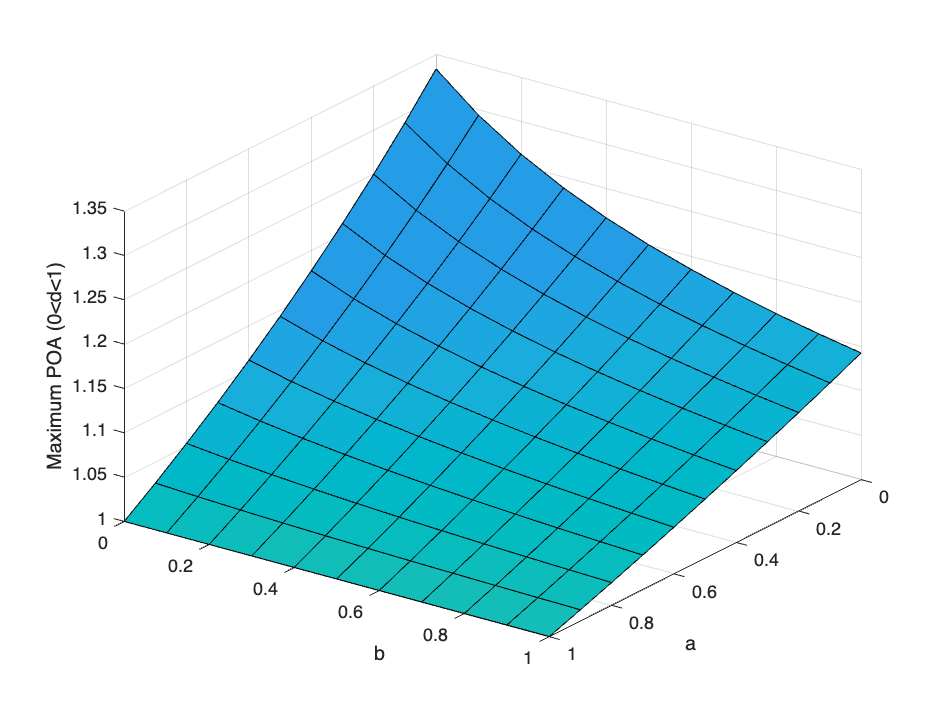

figure;
% plot the function
x = 0:0.1:1;
y = 0:0.1:1;
[X,Y] = meshgrid(x,y);
Z = zeros(size([X,Y]));
for i = 1:length(x)
    for ii = 1:length(y)
        Z(i,ii) = POA_ab([X(i,ii),Y(i,ii)]);
    end
end
surfl(X,Y,Z(:,1:length(x)))
xlabel('a')
ylabel('b')
zlabel('Maximum POA (0<d<1)')

view([126.273 32.113]) % to make it clearer

By inspection it is clear that the maximum POA occurs when both a and b are 0, with the minimum occurring when a is 1. The maximum value of POA is 1.332. a and b both impact this value however only when a is not 1. When lim(a =1 and b=1) the costs for the routes are identical and so the UE and SO solutions will be the same. When lim(a=0 and b=0), the route costs will always remain as x_1 vs 1.

% find minimum
fun = @(x)(-POA_ab(x));
nvars = 2; % a and b
lb = [0,0];
ub = [1,1];
options = optimoptions('particleswarm','SwarmSize',10,MaxIterations=10);
[x, fval] = particleswarm(fun,nvars,lb,ub,options);

Optimization ended: number of iterations exceeded OPTIONS.MaxIterations.


% at maximum POA
a = x(1)

a = 0

b = x(2)

b = 0

Max_POA = -fval

Max_POA = 1.3332

## Q3. Microscoping Modelling

#### a. Analytical expression of maximum flow


$$v\left(\rho \right)=v_0 {\left(1-\frac{\rho }{\rho_{\max } }\right)}^2$$
 

The flow for any velocity is given as 


$$f=v\rho$$



$$f=v_0 \rho -\frac{2v_0 \rho^2 }{\rho_{\max } }+\frac{v_0 \rho^3 }{{\rho^2 }_{\max } }$$



$$\frac{\mathrm{d}}{\mathrm{d}\rho }f=v_0 -\frac{4v_0 \rho }{\rho_{\max } }+\frac{3v_0 \rho^2 }{{\rho^2 }_{\max } }$$


The maximum will occur when


$$\frac{d}{\mathrm{d}\rho }f=0$$


This occurs when (solving for density)

$\rho =\frac{\rho_{\max } }{3}$ or when its equal to maximum density, but this means the flow has stopped.

and so the maximum flow is 


$$f_{\max } =\frac{v\rho_{\max } }{3}$$
 

#### b. Theoretical lower bound of exits N

Theoretical maximum velocity:


$$v\left(\rho =\frac{\rho_{\max } }{3}\right)=\frac{4}{9}v_0$$


So the maximum flow rate of people:


$$f_{\max } =\frac{4v_0 \rho_{\max } }{27}\;\left\lbrack {\textrm{people}\;m}^{-1} s^{-1} \right\rbrack$$


Evacuation area:


$$\textrm{area}=10N\;\left\lbrack m\right\rbrack$$


Evacuation time:

time = 300s

Lower bound of N:


$$\frac{60000}{f_{\max } }=300\times 10\;N\;$$



$$N_{\textrm{LB}} =\frac{135}{v_0 \rho_{\max } }=\frac{135}{\textrm{flow}\;}$$


Plot flow against number of doors needed

clf;
% plot flow against number of doors
flow = 0.1:0.01:2;
N = 60000./(300*10*flow);
% realistic max flow would be 70.8 pers/m min (measured in concert)
% https://www.sciencedirect.com/science/article/pii/S0379711220300448
max_flow = 70.8/60

max_flow = 1.1800

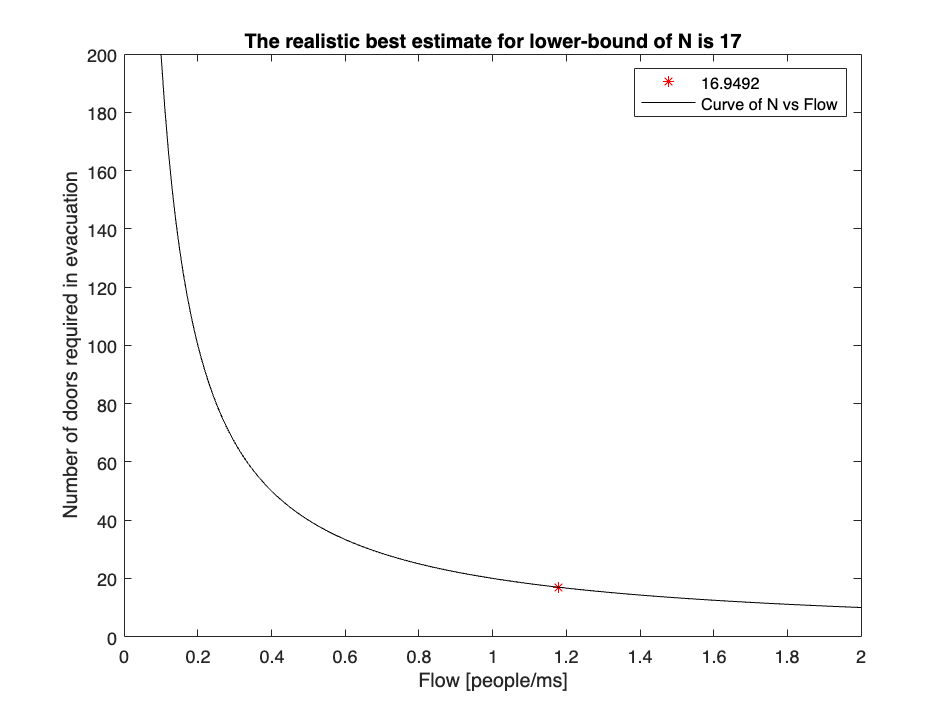

plot(max_flow, 60000/(300*10*max_flow), 'r*', DisplayName=num2str(60000/(300*10*max_flow)));
hold on;
plot(flow,N,'k-', DisplayName='Curve of N vs Flow');
xlabel('Flow [people/ms]');
ylabel('Number of doors required in evacuation');
legend()
title('The realistic best estimate for lower-bound of N is 17')
hold off;

#### c. Numerical value

N = round(135 / (1.3*8))

N = 13

#### d. Detailed microscopic model

Social force model definition:


$$\frac{\mathrm{d}}{\mathrm{d}t}v_{\alpha } \left(t\right)=f_{\alpha } \left(t\right)+\textrm{noise}$$



$$f_{\alpha } \left(t\right)=\frac{1}{\tau_{\alpha } }\left(v_{0_{\alpha } } -v_{\alpha } \right)+\sum_{\beta \left(\not= \alpha \right)} f_{\alpha \beta } \left(t\right)+\sum_i f_{\alpha i} \left(t\right)$$


The equation above shows that the force on a pedestrian is equal to the sum of the acceleration to desired velocity, the sum of forces from other pedestrians, and the sum of forces from boundaries.

- **Each pedestrian is a fan of one of the two teams currently playing. Assume a random allocation of team affinity at the start of the simulation. **

At the start of the simulation, each pedestrian is randomly assigned to one of the two teams (Team A or Team B). Let $T_{\alpha }$ denote the assignment of pedestrian $\alpha$.	


$$\begin{array}{l}
T_{\alpha } =1\;\textrm{or}\;0\\
\textrm{with}:\\
P\left(X=X\right)=\;\;0\ldotp 5\;
\end{array}$$


- **A pedestrian’s desired walking speed will be 50% higher than normal if he/she is currently in a location where there is a majority of fans supporting the other team (within a 10 m radius around the person). 	**	

So at each timestep, the following is calculated:


$$v_{0_{\alpha } } =v_{0_{\alpha } } \times \left(1+0\ldotp 5\times M\right)$$
 

Where M is calculated as followe:

$M\left(\alpha \right)=\frac{\sum_{\beta \;\left(\not= \alpha \right)} 1\;|\;\left(d_{\alpha \beta } <10\;\&\;T_{\beta \;} \not= T_{\alpha } \right)}{\sum_{\beta \;\left(\not= \alpha \right)} 1\;|\;\left(d_{\alpha \beta } <10\;\;\&\;T_{\beta } =T_{\alpha } \right)}$ , $d_{\alpha \beta \;} =\textrm{distance}\;\textrm{between}\;\textrm{supporters}$

the piecewise function:


$$\begin{array}{l}
M=1\;\left\lbrace M\left(\alpha \right)>1\right\rbrace \\
M=0\;\left\lbrace M\left(\alpha \right)\le 1\right\rbrace 
\end{array}$$


(Giving the ratio of supporters of the other team vs supporters of own team and using that as the 1 or 0 piecewise function.)

- **A pedestrian α will be subject to a strong repulsive social force from other pedestrians (β ̸= α) that are (i) within a 5 m radius around the person; and (ii) supporting the other team; and (iii) are located within the 180◦ semi-circle in front of α (i.e., in the direction of motion of α). **


$$f_{\alpha \beta } =w\left(\theta_{\alpha \beta } \right)g\left(d_{\alpha \beta } \right)$$
		

The repulsive force is composed of an angular and distance component. The distance component is modelled as follows:			


$${g\left(d_{\alpha \beta } \right)} =A\times \exp \left(\frac{R-d_{\alpha \beta } }{B}\right)\hat{d_{\alpha \beta } }$$


$F_{\alpha \beta }$ is the force of repulsion from pedestrian $\alpha \;\textrm{to}\;\beta$, acting along the direction of the normalised vector between pedestrians $\hat{d}$.

A is parameter constant that will determine the strength of the repulsive force

B is a parameter constant determining how the repulsive force decays with distance between pedestrians. With a small value of B, e.g. 0.1, the force will be very high within 5m and decay very quickly as the distance increases further.

The force is only applied if the distance $d_{\alpha \beta \;} <R$ is less than the radius (5m)

The angular component can be modelled as follows:


$$w\left(\theta_{\alpha \beta } \right)=\lambda +\left(1-\lambda \right)\frac{1-\cos \left(\theta_{\alpha \beta } \right)}{2}$$
 

If $\lambda =1,\textrm{the}\;\textrm{force}\;\textrm{is}\;\textrm{equal}\;\textrm{for}\;\textrm{all}\;\textrm{values}\;\textrm{of}\;\theta ,\textrm{if}\;\lambda =0,\textrm{the}\;\textrm{force}\;\textrm{is}\;\textrm{only}\;\textrm{active}\;\textrm{for}\;\frac{\pi }{2}\le \theta \le 3\frac{\pi }{2}$

For the purpose of the model, it can be either modelled by using a value of $\lambda =0$, and this will give a cardiod-like shape in the forward direction.

or a piecewise function defined as:


$$w\left(\theta_{\alpha \beta } \right)\;=1,\;\;\;\;\frac{\pi }{2}\le \theta \le 3\frac{\pi }{2}$$



$$w\left(\theta_{\alpha \beta } \right)\;=0,\;\;\;\textrm{else}$$


Calculating the angle, where v is the velocity vector of the pedestrians. A head-on course results in an angle of pi - the point where a repulsive force is required.


$$\cos \left(\theta_{\alpha \;\beta } \right)=\frac{v_{\alpha } \cdot v_{\beta } }{|v_{\alpha } |\;|v_{\beta } |}$$


#### Example code

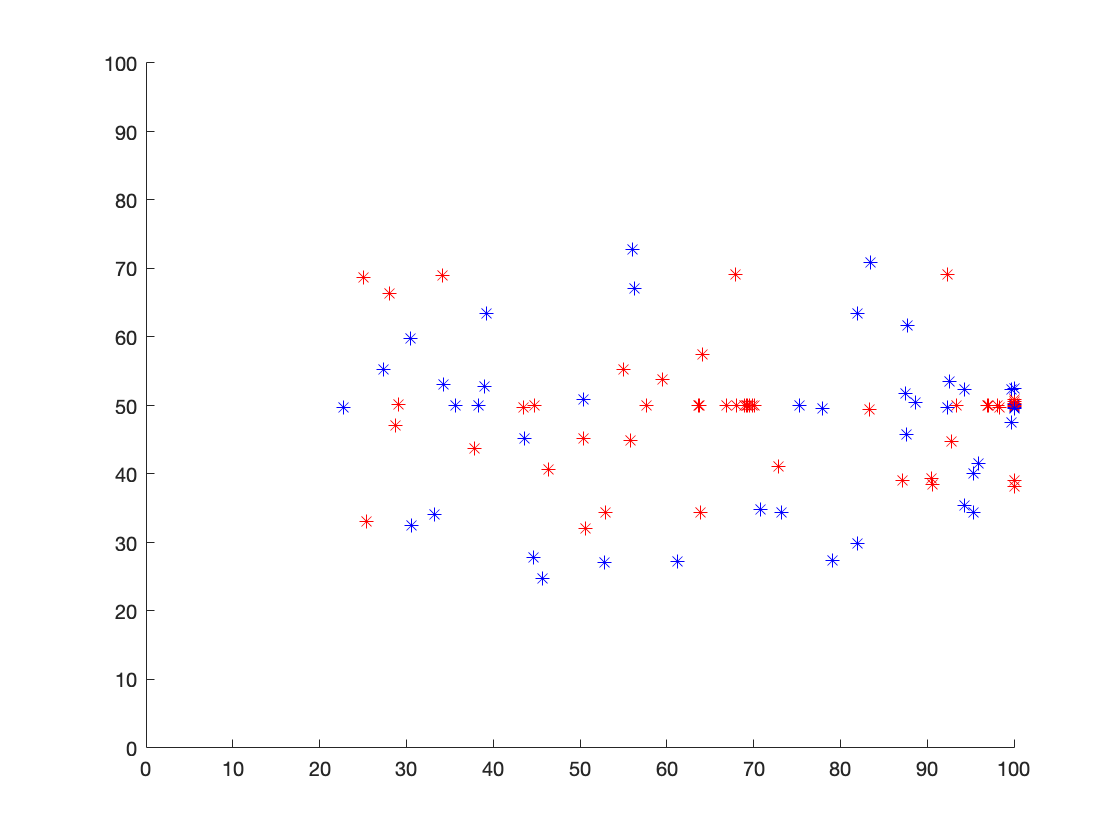

% building a microscopic model of fans
% v(ρ) = v0(1 − ρ/ρmax)2
% define space
size_x = 100;
size_y = 100;
x = 0:0.1:size_x;
y = 0:0.1:size_y;
N = 100;
v0 = 1;
v_max = 1;
rho_max = 8;

% generate N pedestrians (x,y,vx0,vy0, Vx, Vy)
pedestrians = zeros(N,6);
% set v0 for all pedestrians - they are all trying to leave via the right
% had side middle 
pedestrians(:,3) = 0;
pedestrians(:,4) = 0;

p_colours = zeros(N,3);

% init loop
for alpha = 1:N
%     place the pedestrian in a random location within boundary
    x_p = rand(1)*size_x;
    y_p = rand(1)*size_y;
    pedestrians(alpha,1)=x_p;
    pedestrians(alpha,2)=y_p;
   
%   assign to team randomly
%   initially
    if randi(2)>1
%         plot(x_p,y_p, '*', Color='b');
        p_colours(alpha,:) = [0,0,1]; 
    else
%         plot(x_p,y_p, '*', Color='r');
        p_colours(alpha,:) = [1,0,0];
    end
end
% timestepping
steps = 50;
figure;
for t = 1:steps
    clf
    for alpha = 1:N
        density_count = 0;

        % update v0
        [pedestrians(alpha,3), pedestrians(alpha,4)] =...
            v0_fun(pedestrians(alpha,1), pedestrians(alpha,2),size_x,size_y/2);
    
        % pedestrian v0 is 50% higher if majority other team within 10m
        radius = 10;
        for beta = 1:N
            if alpha ~= beta && p_colours(alpha) ~= p_colours(beta)
                if distance(pedestrians(alpha,:),pedestrians(beta,:)) < radius
                    pedestrians(alpha,3:4) = pedestrians(alpha,3:4) * 1.5;
                    density_count = density_count+1;
                end
            end
        end

        % repulsive force
        radius2 = 5;
        A = 10; 
        B = 0.1; 
        for beta = 1:N
            if alpha ~= beta && p_colours(alpha) ~= p_colours(beta)
                if distance(pedestrians(alpha,:),pedestrians(beta,:)) < radius2
                % Calculate the normalized vector between pedestrians
                normalized_vector=(pedestrians(alpha,1:2)-pedestrians(beta,...
                    1:2))/distance(pedestrians(alpha,:),pedestrians(beta,:));

                % Calculate the angle between the velocity and the normalized vector
                angle = acos(dot(pedestrians(alpha,3:4), normalized_vector) /...
                    norm(pedestrians(alpha,3:4)));

                % Repulsive force components
                distance_force = A * exp(-B * distance(pedestrians(alpha,:),...
                    pedestrians(beta,:))) * normalized_vector;
                angular_force = 1 * angle * normalized_vector; 

                % Total repulsive force
                repulsive_force = distance_force + angular_force;

                % Update the velocity based on the repulsive force
                pedestrians(alpha, 3:4) = pedestrians(alpha, 3:4)...
                    + repulsive_force;
                end
            end
        end

        rho = rho_fun(density_count, radius);
        pedestrians(alpha, 5:6) = vel_fun(pedestrians(alpha,3:4), rho, rho_max);
        vel = sqrt(pedestrians(alpha,5)^2 + pedestrians(alpha,6)^2);
        if vel > v_max
            pedestrians(alpha,5:6) = pedestrians(alpha,5:6) * v_max/vel;
        end
        
        % update location (red travel right, blue travel left) with
        % deletion for dissapearance
        new_x = pedestrians(alpha,5) + pedestrians(alpha,1);
        new_y = pedestrians(alpha,6) + pedestrians(alpha,2);
        test_x = new_x - size_x;
        test_y = new_y - size_y;
        if test_x > 0
            pedestrians(alpha,1) = size_x;
        else
            pedestrians(alpha,1) = new_x;
        end
        if test_y > 0
            pedestrians(alpha,2) = size_y;
        else
            pedestrians(alpha,2) = new_y;
        end

        hold on
        plot(pedestrians(alpha,1),pedestrians(alpha,2),...
            '*', 'Color', p_colours(alpha,:));
        xlim([0 100]);
        ylim([0 100]);

    end
    pause(0.01)  
    hold off% Pause for 0.01 s
end

Animation of two teams leaving through a single narrow door on the right hand side.

## Q4. Data-driven modelling

#### a. Centrality measures

#### i. Direct demand model

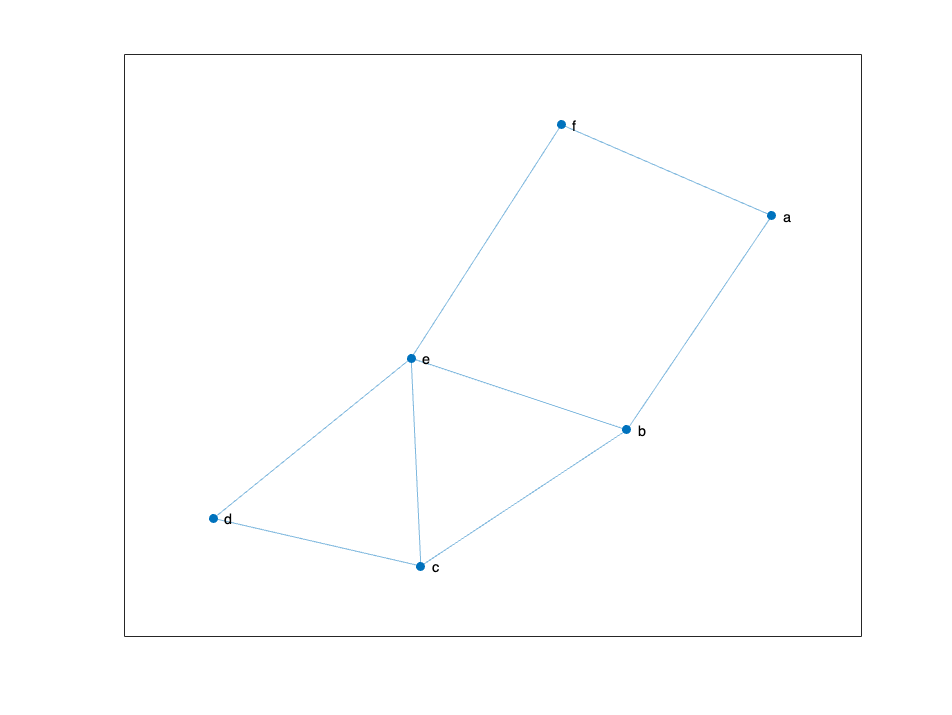

% The nodes are defined clockwise from top-left
clf;
% Create a graph
nodes = {'a','b','c','d','e','f'};
edges = {'a','b'; 'b','c'; 'c','d'; 'd','e'; 'e','f'; 'f','a'; 'c','e'; 'b','e'};
G = graph(edges(:, 1), edges(:, 2));
% Compute centralities
betweenness = centrality(G, 'betweenness');
degree = centrality(G, 'degree');
closeness = centrality(G, 'closeness');

% Known real values
real_val = [7,4.5,3,6,5.5,5.5];

% Plot the graph
plot(G, 'NodeLabel', G.Nodes.Name);

% use a regression model
R = fitlm(real_val(1:5)',betweenness(1:5)')

R = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat      pValue 
                   ________    _______    ________    _______

    (Intercept)      2.1882     2.9873     0.73249    0.51691
    x1             -0.14516    0.55569    -0.26123    0.81082


Number of observations: 5, Error degrees of freedom: 3
Root Mean Squared Error: 1.69
R-squared: 0.0222,  Adjusted R-Squared: -0.304
F-statistic vs. constant model: 0.0682, p-value = 0.811

predictions = 2.1882 - 0.14516.*(betweenness);
percent_err = (real_val(6) - predictions(6))*100/ real_val(6) 

percent_err = 62.4139

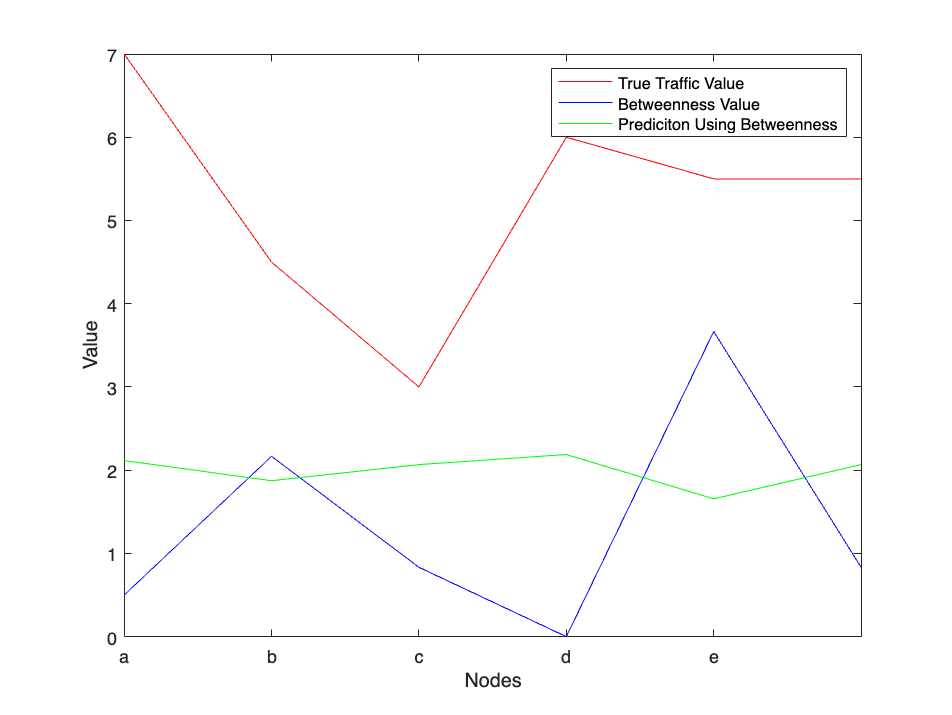

% plot the real values and betweenness
plot(1:6,real_val, 'Color','r', DisplayName='True Traffic Value')
hold on
plot(1:6,betweenness,'Color','b',DisplayName='Betweenness Value')
plot(1:6,predictions,'Color','g',DisplayName='Prediciton Using Betweenness')
xticks(1:5)
xticklabels(nodes)
xlabel('Nodes')
ylabel('Value')
legend

As shown in the graph, the betweenness value does not correlate very well with the true amount of traffic measured, with a RMSE = 1.69, implying a weak correlation, and a direct prediction using the betweeness value gives an 62% error.

#### ii. Alternative model

Assume all lengths in graph = 1, using the inverse distance weighting


$$\rho_o =\frac{\sum_i \frac{\rho_i }{d_{\textrm{oi}} }\;}{\sum_i \frac{1}{d_{\textrm{oi}} }}$$


% for node f:
distances_f = [1,2,2,2,1]; % the distances of nodes from f (clockwise)
numerator = sum(real_val(1:5)./distances_f);
denominator = sum(ones(1,5)./distances_f);
prediction = numerator/denominator

prediction = 5.5000

error = prediction - real_val(6)

error = 0

#### b. Bristol road time series

#### i. Dynamics description

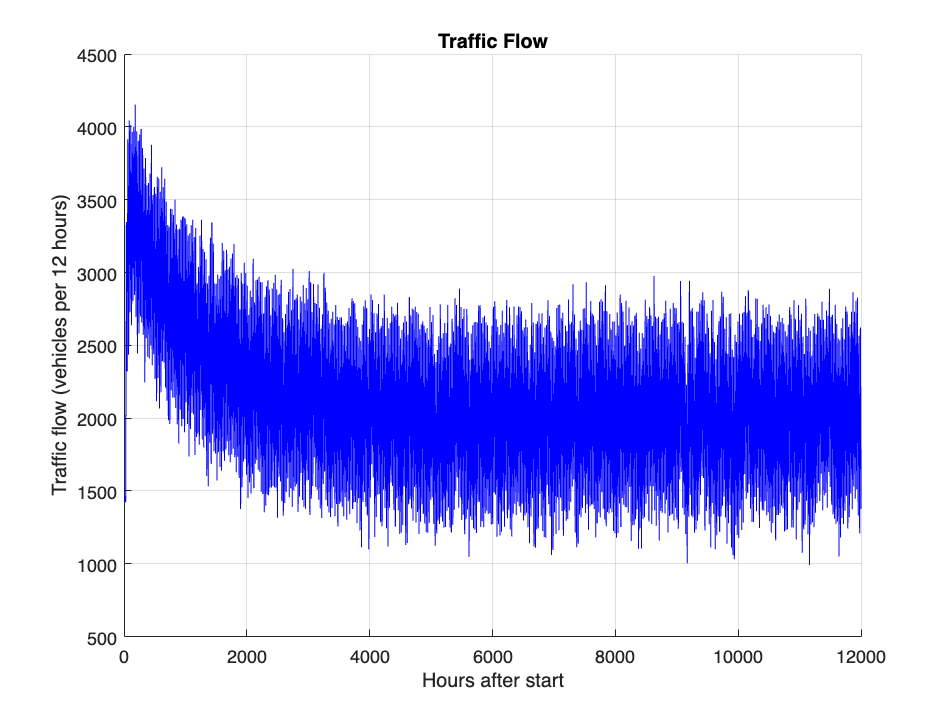

% define constants
alpha = 0.99;
beta = 0.5;
s = 4;
sigma = 0.1;

% starting conditions
Y_0 = 0;
a_0 = 0.75;
c_0 = 0.5;
% plot Y as a function of t
figure
hold on
timesteps = 1:1000;
vals = zeros(length(timesteps),3);
for t = timesteps
    [Y_1, a_1, c_1] = Y_t(alpha, beta, s, sigma, a_0, Y_0, c_0);
    Y_0 = Y_1;
    a_0 = a_1;
    c_0 = c_1;
    vals(t,:) = [Y_0, a_0,c_0];
end
hours = timesteps * 12;
vehicles = vals(:,1) * 1000;

plot(hours,vehicles, '-', Color='b');
xlabel('Hours after start')
ylabel('Traffic flow (vehicles per 12 hours)')
title('Traffic Flow');
grid on;
hold off;

This shows the traffic flow on the road in bristol. The traffic flow increases rapidly at the beginning up to a maximum of around 4000 vehicles / 12 hours and slowly decreases to a level of around 2000 vehicles / 12 hours at which it stays relatively constant into the future. The time series is noisy with the flow constantly varying.

**Influence of each term:**

**a(t): **Autoregressive component, this component is influenced by its past value, and therefore suggests a slow decay of this component and a relationship to its previous state.

**b(t): **This component references the previous value of traffic (Y) and so adds a consistent decay into the model through a lag component, where it references the previous time step.

**c(t): **Seasonal component, due to the use of the cosine term, it creates periodic behaviour in the model. In this case it is likely used to model increases in traffic during half of the day. (it must be slowly increasing to account for the decay due to a and b, for the model to stabilise as it does.)

**d(t): **Noise component, adds the randomness associated with traffic data, attempting to account for short term fluctuations not described in the components above, for example changes in traffic due to weather, accidents or events.

#### ii. Discuss usefulness of model 

- When looking at the model for a smaller number of time steps it becomes clear that there is a seasonal term increasing during the night and decreasing during the day which would likely be incorrect, unless this road has bars, nightclubs and restaraunts exclusively. A model of a general street would likely shift this term by 1 timestep (12 hours).

- It is unlikely that a true road would have its greatest usage during the first timesteps of its operation, and so it is more likely that the stable section of the time series (after approximately 300 timesteps) would be used to model a general road. This is  unless this road provides some form of improvement to peoples journeys (while its new) which then decreases as the road is used more, this could be due to road surface quality deteriorating for example.

- The model should be validated against real traffic data from the Bristol road to assess its performance and identify areas for improvement - although the parameters have been estimated based on data, a side by side comparison could allow for greater analysis and better fine tuning. Additionally, other components could be introduced to improve accuracy.

- Another point of improvement would be to include a further seasonal term for weekends, likely reducing the flow if its a commuter heavy road.

% calculate the drift and diffusion of the data
% Fit a linear regression to estimate drift
X = [ones(length(timesteps), 1), hours'];
coefficients = X \ vehicles;
drift = coefficients(2)

drift = -0.0552

The drift component shows the average change in traffic value over time, it would likely be zero if only looking at the long term of this model, and would be highly negative in the short term.

% Calculate residuals to estimate diffusion
residuals = vehicles - X * coefficients;
diffusion = std(residuals)

diffusion = 712.6575

This diffusion term represents the sum of the average daily fluctuations and noise to show how much the model varies timestep to timestep - i.e. every 6 hours.

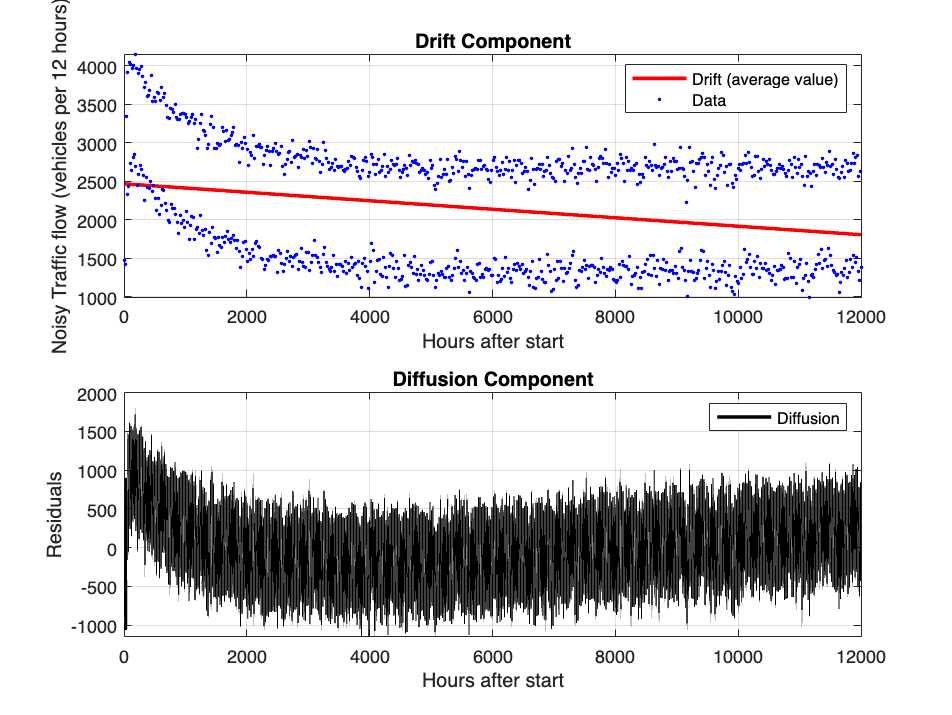

% Plot drift and diffusion components
figure;
subplot(2, 1, 1);
plot(hours, drift * hours + coefficients(1), 'r-', 'LineWidth', 2);
hold on;
scatter(hours, vehicles, 'b.');
xlabel('Hours after start');
ylabel('Noisy Traffic flow (vehicles per 12 hours)');
title('Drift Component');
legend('Drift (average value)','Data')
grid on;

subplot(2, 1, 2);
plot(hours, residuals, 'k-', 'LineWidth', 2);
xlabel('Hours after start');
ylabel('Residuals');
title('Diffusion Component');
legend('Diffusion')
grid on;

Drift: Represents the average rate of change of the traffic flow over time. This indicates that the traffic is gradually decreasing over time but only from the initial few hours. The drift term would likely be zero if only considering the long term model as the model finds a stable point after approximately 300 timesteps.

Diffusion: Magnitude of randomness. This would generally represents the random fluctuations or uncertainties in the traffic flow, however for this time-series is shows the variation due to the seasonal term. This shows that initially there is a lot of randomness and a lot of daily variation in the flow, which then quickly drops and then gradually increases. These fluctuations tend to show that for long term prediction the randomness is increasing, this would likely be inaccurate as the usage of a road would tend to stabilise.

## All Functions

function sol = UE_sol(H, f, Aeq, beq, options)
    sol = quadprog(H, f, [], [], Aeq, beq, [0,0],[],[], options);
end

function sol = SO_sol(H,f, Aeq, beq, options)
    sol = quadprog(2*H, f, [], [], Aeq, beq, [0,0],[],[], options);
end

function max_poa = POA_ab(x)
    options = optimoptions('quadprog', 'Display', 'off');

    % unpackage a and b
    a_var = x(1);
    b_var = x(2);

    % Initialize matrices to store solutions
    d_values = 0:0.1:1;  
    x_ue_vals = zeros(length(d_values), 2); 
    x_so_vals = zeros(length(d_values), 2); 
    
    cost_ue = zeros(length(d_values),1);
    cost_so = zeros(length(d_values),1);
    
    % Solve the UE problem for each demand value
    for i = 1:length(d_values)
        d = d_values(i);
    
    % Define matrix H, f, and equality constraint
        H = [1, 0; 0, b_var];
        f = [a_var; 1];
        Aeq = [1, 1];
        beq = d;
        
    % Solve the quadratic programming problem using quadprog
        x_ue = quadprog(H, f, [], [], Aeq, beq,[0,0],[],[], options);
        x_so = quadprog(2*H, f, [],[], Aeq, beq,[0,0],[],[], options); 
        % H*2 in this case is the Beckmann Formulation
        
    % Store the solution
        x_ue_vals(i, :) = x_ue';
        x_so_vals(i, :) = x_so';
    
        cost_ue(i) = x_ue_vals(i,1)*(a_var + x_ue_vals(i,1))...
            + x_ue_vals(i,2)*(1+b_var*x_ue_vals(i,2));
        cost_so(i) = x_so_vals(i,1)*(a_var + x_so_vals(i,1))...
            + x_so_vals(i,2)*(1+b_var*x_so_vals(i,2));
    end

    % POA 
    poa = cost_ue./cost_so;
    % find max POA
    max_poa = max(poa);
end

function velocity = vel_fun(v0, rho, rho_max)
       velocity = v0*(1-rho/rho_max)^2;
end

function density = rho_fun(N, radius)
        density = N/(pi*radius^2);
end

function [v0x,v0y] = v0_fun(x,y, xt,yt)
    % calculate angle
    v0x = (xt - x);
    v0y = (yt - y);
    v0x = v0x/sqrt(v0x^2 + v0y^2);
    v0y = v0y/sqrt(v0x^2 + v0y^2);

end

function dist = distance(alpha, beta)
    x1 = alpha(1); y1 = alpha(2);
    x2 = beta(1); y2 = beta(2);
    dist = sqrt((x2-x1)^2 + (y2-y1)^2);
end


function [Y_1, a_1, c_1] = Y_t(alpha, beta, s, sigma, prev_a,prev_y, prev_c)

    a_1 = alpha * prev_a;
    b_1 = beta * prev_y;

    c = 0;
    for j = 1:(s/2)
        c = c + cos(2*pi*j*prev_c/s);
    end
    c_1 = c;

    d_1 = normrnd(0,sigma);

    Y_1 = a_1 + b_1 + c_1 + d_1;

end


# PART B: Essay